% Reset
close all;
clear all;

%%%%%%%%%%               User configurations               %%%%%%%%%%
hold on;
axesColor = 'Black';
% Set default plot limits
xlimCfg = [-650, 650];
ylimCfg = xlimCfg;
zlimCfg = xlimCfg;
% Set axes labels
xlab = 'i';
ylab = 'j';
zlab = 'k';
aspect = [1, 1, 1];
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Ejercicio 1.10 Lámpara asimétrica original

Describa vectorialmente el diseño de la lámpara siguiendo el diseño mostrado en la figura y demuestre que el punto de sujeción de la lámpara al techo se encuentra precisamente en el centro de masa.

### Diseño vectorial

Para facilitar el diseño se realizan las siguientes consideraciones:

- La lámpara está  construida por 6 segmentos.  De los cuales, 3 tienen una distancia de 450mm y los otros 3 de 600mm.

- Los 6 segmentos están distribuidos equitativamente en un círculo. Por lo tanto, la distancia entre cada uno, será:

        
$$\frac{360°}{6}=60°$$


- Si se toma en cuento que el peso de todas las esferas se encuentra aplicado en el mismo plano z y que por lo tanto, las 6 fuerzas están en el $z=0$, el equilibrio únicamente se verá afectado por la posición de las esferas con respecto a $x\;$y $y$. Para ello, se puede realizar una representación en $\Re^2$, donde el origen (0,0) será el  punto de anclaje de la lámpara, el eje $i$, será formado por los brazos 1 y 4. Mientras que el eje $j$, será perpendicular al eje $i$, pasando por el origen.

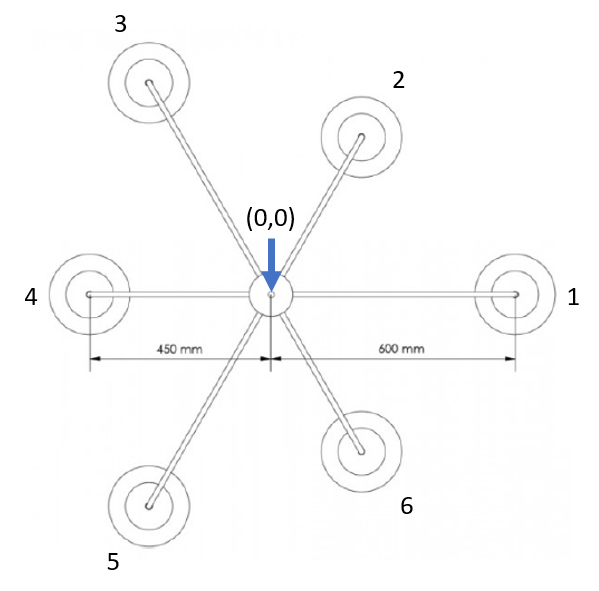

- Cada uno de los brazos se numerará como en la imagen superior.

### Brazo 2 y 6

El centro de las esferas en los brazos 2 y 6 se encuentran a la misma distancia absoluta del eje $i$ y a la misma distancia del eje $j$. Por lo que si el brazo 2 es el vector $v$ y el brazo 6 el vector $w$,se podrá obtener el valor de $w$ a partir de $v$.

$v=\left\lbrack \begin{array}{c}
i_2 \\
j_2 
\end{array}\right\rbrack$           y          $w\;=\left\lbrack \begin{array}{c}
i_6 \\
j_6 
\end{array}\right\rbrack$


$$w=\left\lbrack \begin{array}{c}
i_2 \\
{-j}_2 
\end{array}\right\rbrack$$


Sea el brazo 2 el $v$ y el brazo 1 $w$

$v\;=\left\lbrack \begin{array}{c}
i\\
j
\end{array}\right\rbrack$   y  $w=\left\lbrack \begin{array}{c}
i\\
j
\end{array}\right\rbrack$

Donde se conoce


$$v\;=\left\lbrack \begin{array}{c}
i\\
j
\end{array}\right\rbrack$$
              
$$\parallel v\parallel =450\mathrm{mm}$$



$$w=\left\lbrack \begin{array}{c}
600\\
0
\end{array}\right\rbrack$$
             
$$\parallel w\parallel =600\mathrm{mm}$$
 


$$\theta =60°$$


Utilizando la representación geométrica del producto punto con el ángulo


$$v\cdot w\;=\;\parallel v\parallel \cdot \parallel w\parallel \mathrm{cos}\theta$$


Sustituyendo $v$ y $w$


$$\mathrm{cos}\left(60°\right)=\frac{\left\lbrack \begin{array}{c}
i\\
j
\end{array}\right\rbrack \cdot \left\lbrack \begin{array}{c}
600\\
0
\end{array}\right\rbrack }{\left(450\right)\left(600\right)}$$



$$0\ldotp 5=\frac{600i}{270,000}$$


Despejando para $i$


$$i=\frac{135,000}{600}=225$$


Utilizando $\parallel v\parallel$ se puede obtener el valor de $j_w$


$$\parallel v\parallel =\sqrt{{225}^2 +j^2 }=450$$



$$j=\sqrt{{450}^2 -{225}^2 }$$



$$j=389\ldotp 71$$


Por lo tanto, para el brazo 2


$$v\;=\left\lbrack \begin{array}{c}
225\\
389\ldotp 71
\end{array}\right\rbrack$$


Por lo que el brazo, el brazo 6


$$v\;=\left\lbrack \begin{array}{c}
225\\
-389\ldotp 71
\end{array}\right\rbrack$$


% Brazo 1, 2, 4 y 6
l1 = line([0, 600], [0, 0], 'color', 'black');          % 1
l2 = line([0, 225], [0, 389.71], 'color', 'cyan');      % 2
l4 = line([0, -450], [0, 0], 'color', 'black');         % 4
l6 = line([0, 225], [0, -389.71], 'color', 'green');    % 6
legend([l1, l2, l6],["Brazo 1 y 4", "Brazo 2", "Brazo 6", ])

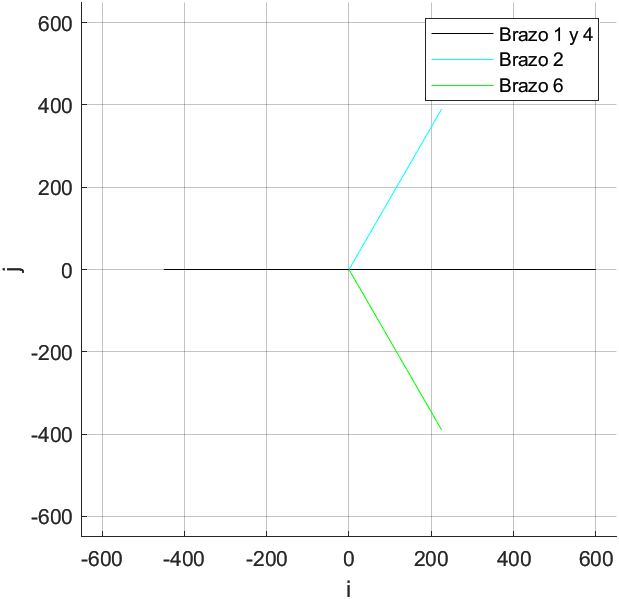

%%%%%%%%%%             Configuration of figure (plot)             %%%%%%%%%%
% Configure cartesian plot
xlim(xlimCfg);
ylim(ylimCfg);
xlabel(xlab);
ylabel(ylab);
zlabel(zlab);
grid on;
pbaspect(aspect);
hold off;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

### Brazo 3 y 5

El centro de las esferas en los brazos 3 y 5 se encuentran a la misma distancia absoluta del eje $i$ y a la misma distancia del eje $j$. Por lo que si el brazo 3 es el vector $v$ y el brazo 5 el vector $w$,se podrá obtener el valor de $w$ a partir de $v$.

$v=\left\lbrack \begin{array}{c}
i_3 \\
j_3 
\end{array}\right\rbrack$           y          $w\;=\left\lbrack \begin{array}{c}
i_5 \\
j_5 
\end{array}\right\rbrack$


$$w=\left\lbrack \begin{array}{c}
i_3 \\
{-j}_3 
\end{array}\right\rbrack$$


Sea el brazo 3 el $v$ y el brazo 4 $w$

$v\;=\left\lbrack \begin{array}{c}
i\\
j
\end{array}\right\rbrack$   y  $w=\left\lbrack \begin{array}{c}
i\\
j
\end{array}\right\rbrack$

Donde se conoce


$$v\;=\left\lbrack \begin{array}{c}
i\\
j
\end{array}\right\rbrack$$
              
$$\parallel v\parallel =600\mathrm{mm}$$



$$w=\left\lbrack \begin{array}{c}
-450\\
0
\end{array}\right\rbrack$$
             
$$\parallel w\parallel =450\mathrm{mm}$$
 


$$\theta =60°$$


Utilizando la representación geométrica del producto punto con el ángulo


$$v\cdot w\;=\;\parallel v\parallel \cdot \parallel w\parallel \cos \theta$$


Sustituyendo $v$ y $w$


$$\mathrm{cos}\left(60°\right)=\frac{\left\lbrack \begin{array}{c}
i\\
j
\end{array}\right\rbrack \cdot \left\lbrack \begin{array}{c}
-450\\
0
\end{array}\right\rbrack }{\left(600\right)\left(450\right)}$$



$$0\ldotp 5=\frac{-450i}{270,000}$$


Despejando para $i$


$$i=\frac{135,000}{-450}=-300$$


Utilizando $\parallel v\parallel$ se puede obtener el valor de $j_w$


$$\parallel v\parallel =\sqrt{{-300}^2 +j^2 }=600$$



$$j=\sqrt{{600}^2 -{\left(-300\right)}^2 }$$



$$j=519\ldotp 615$$


Por lo tanto, para el brazo 3


$$v\;=\left\lbrack \begin{array}{c}
-300\\
519\ldotp 615
\end{array}\right\rbrack$$


Por lo que el brazo, el brazo 5


$$v\;=\left\lbrack \begin{array}{c}
-300\\
-519\ldotp 615
\end{array}\right\rbrack$$


hold on;
% Brazo 1, 2, 3, 4, 5y 6
l1 = line([0, 600], [0, 0], 'color', 'black');          % 1
l2 = line([0, 225], [0, 389.71], 'color', 'cyan');      % 2
l3 = line([0, -300], [0, 519.615], 'color', 'red');     % 3
l4 = line([0, -450], [0, 0], 'color', 'black');         % 4
l5 = line([0, -300], [0, -519.615], 'color', 'blue');   % 5
l6 = line([0, 225], [0, -389.71], 'color', 'green');    % 6
legend([l1, l2, l3, l5, l6],["Brazo 1 y 4", "Brazo 2", "Brazo 3", "Brazo 5", "Brazo 6", ])

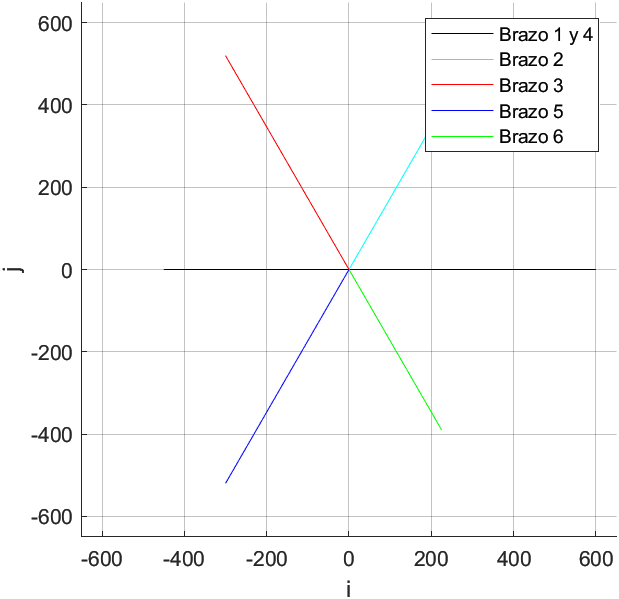

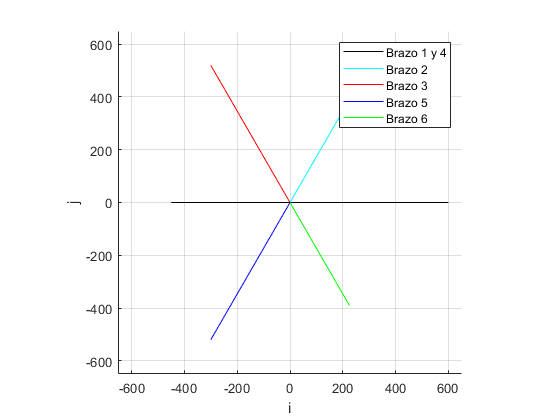

%%%%%%%%%%             Configuration of figure (plot)             %%%%%%%%%%
% Configure cartesian plot
xlim(xlimCfg);
ylim(ylimCfg);
xlabel(xlab);
ylabel(ylab);
zlabel(zlab);
grid on;
pbaspect(aspect);
hold off;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

### Centro de masa

Debido a que se seleccionó el punto de sujeción de la lámpara como el origen (0,0). Basta con comprobar que el ${\mathrm{COM}}_x =0$ y que ${\mathrm{COM}}_y =0$.


$${\mathrm{COM}}_x =\frac{m_1 x_1 +m_2 x_2 +\cdots m_n x_n }{m_1 +m_2 +\cdots +m_n }$$



$${\mathrm{COM}}_y =\frac{m_1 y_1 +m_2 y_2 +\cdots m_n y_n }{m_1 +m_2 +\cdots +m_n }$$


Sustituyendo


$${\mathrm{COM}}_i =\frac{350\left(600+225-300-450-300+225\right)}{350\left(6\right)}=\frac{\left(0\right)}{6}=0$$



$${\mathrm{COM}}_j =\frac{350\left(0+389\ldotp 71+519\ldotp 615+0-519\ldotp 615-389\ldotp 71\right)}{350\left(6\right)}=\frac{\left(0\right)}{6}=0$$


Por lo tanto, el centro de masa si está en el punto de sujeción de la lámpara.